# Matlab文件IO

## 文件夹管理

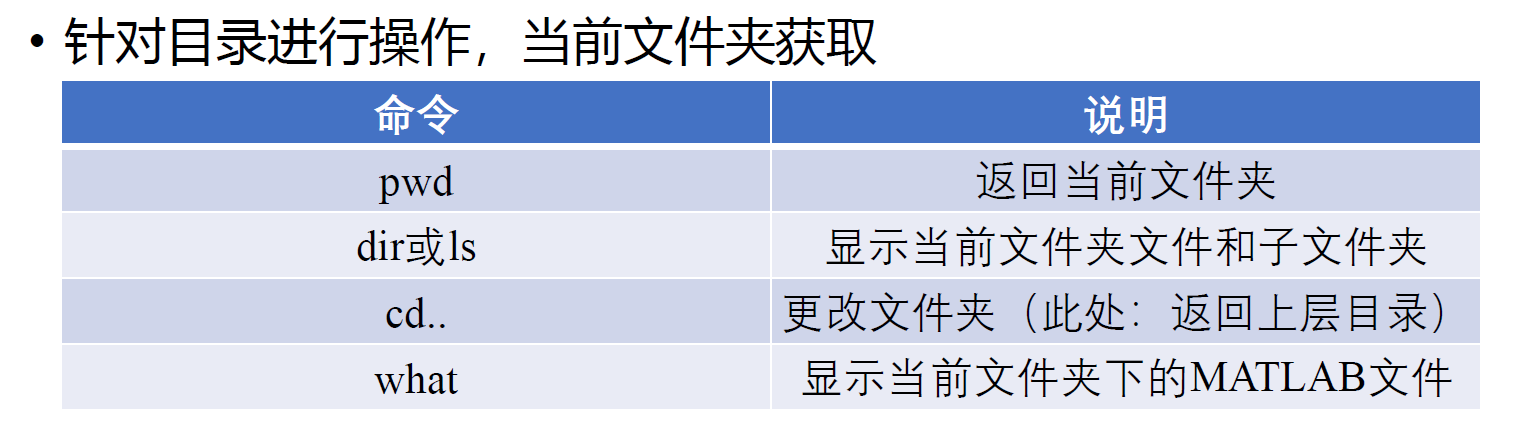

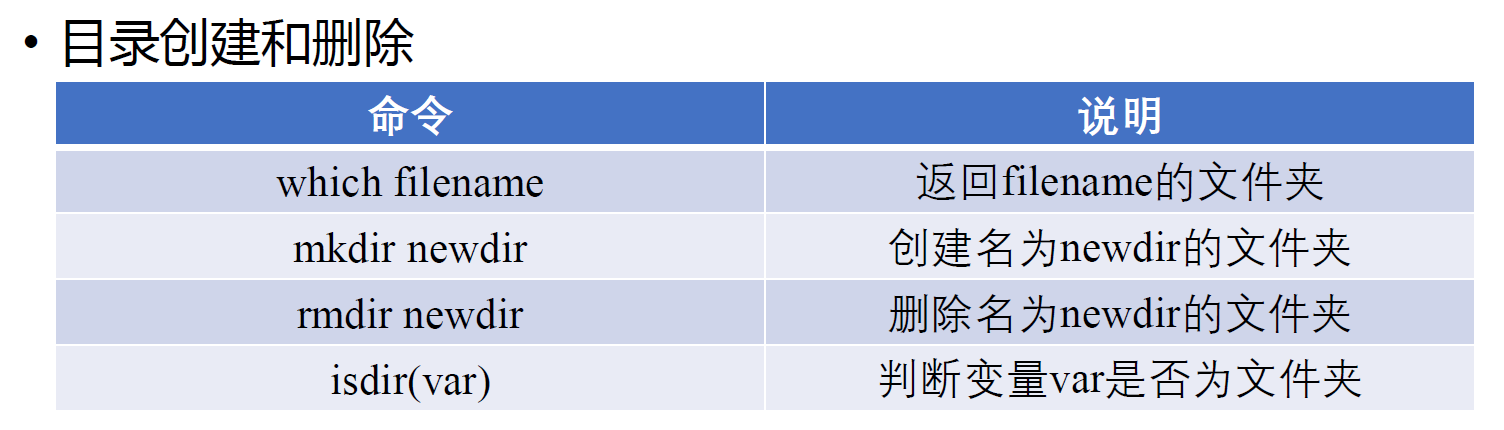

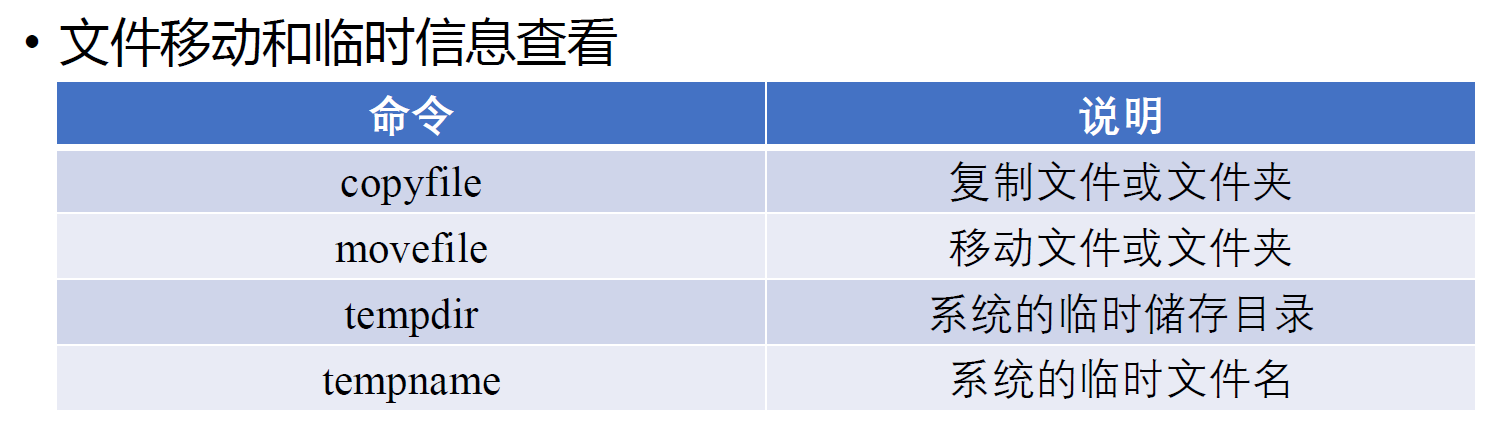

**dir和ls的区别**

% dir返回的是结构体，包括文件名、日期、时间、大小等信息
% ls返回的是字符串，只包含路径和文件名
A = dir

A = 包含以下字段的 8×1 struct 数组:
    name
    folder
    date
    bytes
    isdir
    datenum


B = ls

B = 8×13 char 数组
    '.            '
    '..           '
    'Administrator'
    'All Users    '
    'Default      '
    'Default User '
    'Public       '
    'desktop.ini  '


[status,msg,msgID] = mkdir('testDir')

status = logical
   0


msg =     '拒绝访问。
     '


msgID = 'MATLAB:MKDIR:OSError'

% mkdir
% 具有包含信息的返回值，包括是否创建成功和已知的错误提示
% 在进行训练、迭代之前可能会涉及到保存文件创建的问题，根据提示进行操作

% rmdir 删除文件夹
% movefile 移动或重命名文件夹

## 文件使用

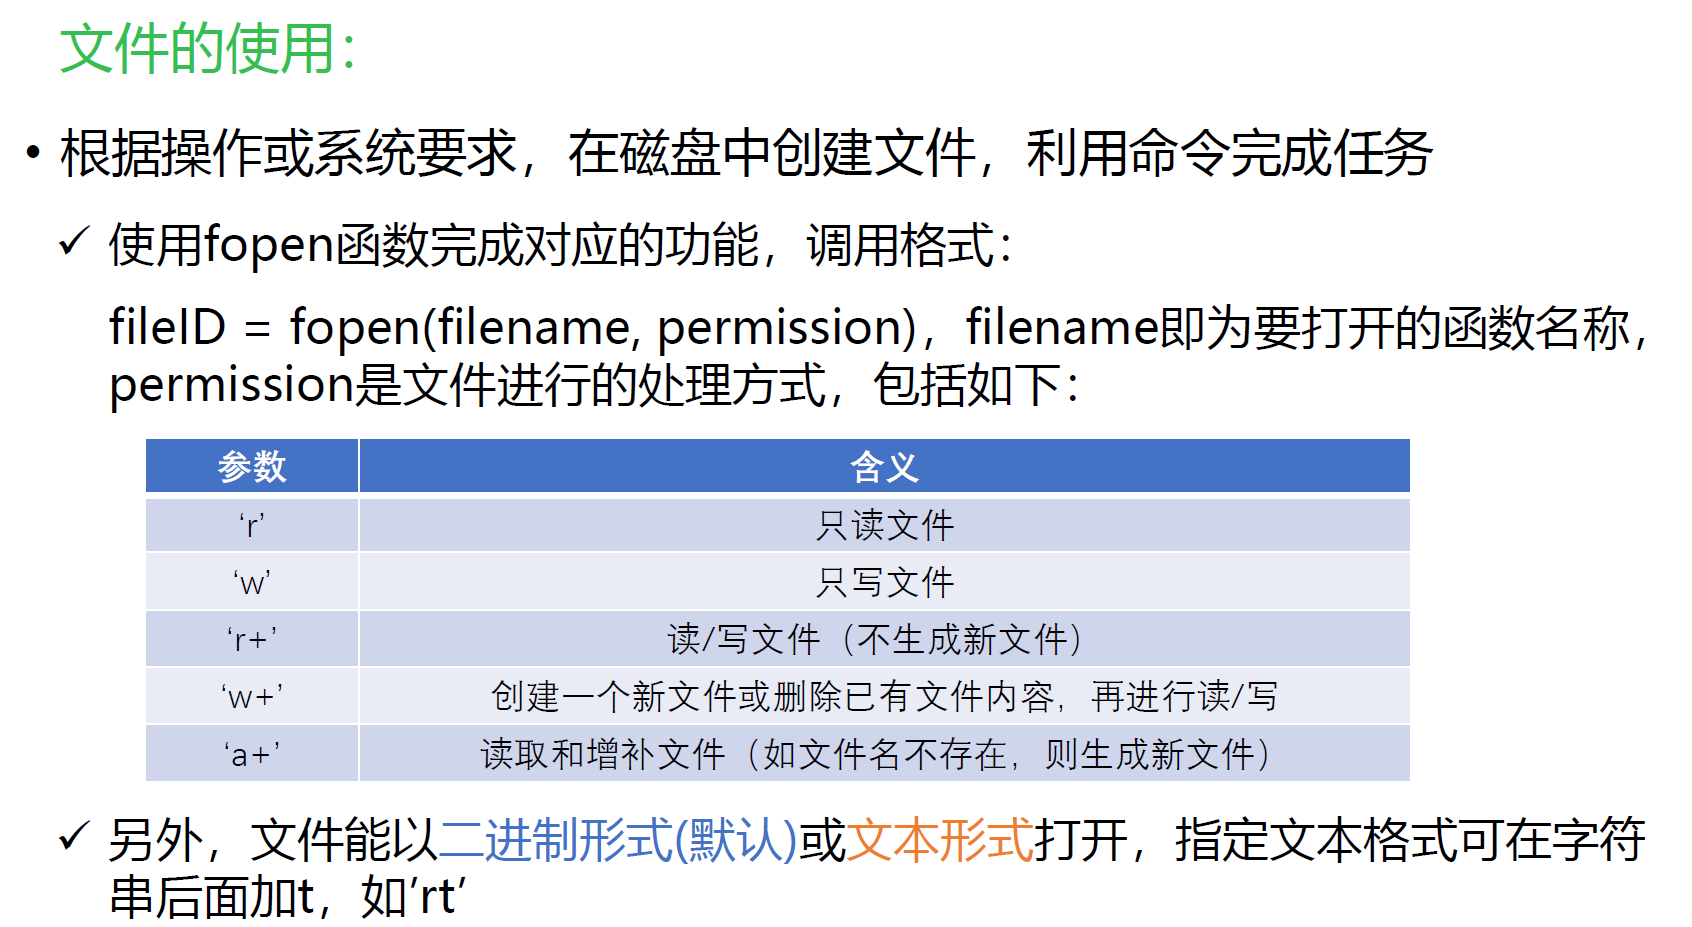

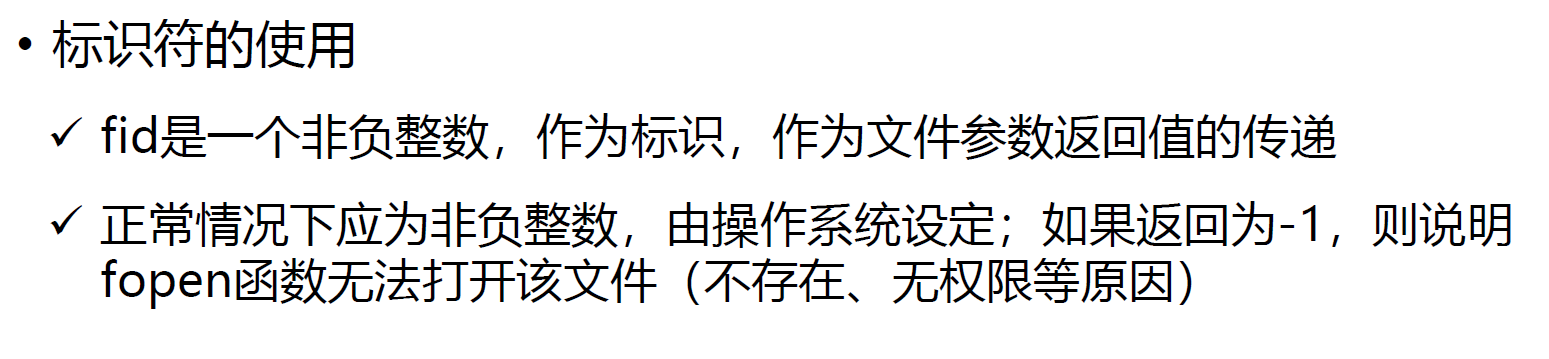

[fid,meg] = fopen('data.txt','r');
disp(fid);

    -1



disp(meg);

No such file or directory


### fclose(fileID)

fp = fopen('data.txt','r');
fclose(fp);

错误使用 fclose
文件标识符无效。使用 fopen 生成有效的文
件标识符。

## 数据存取

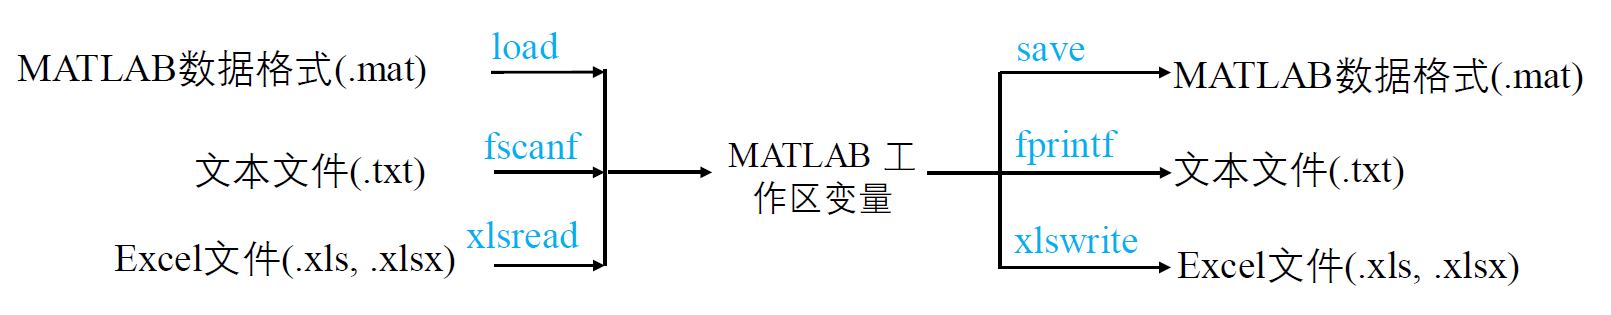

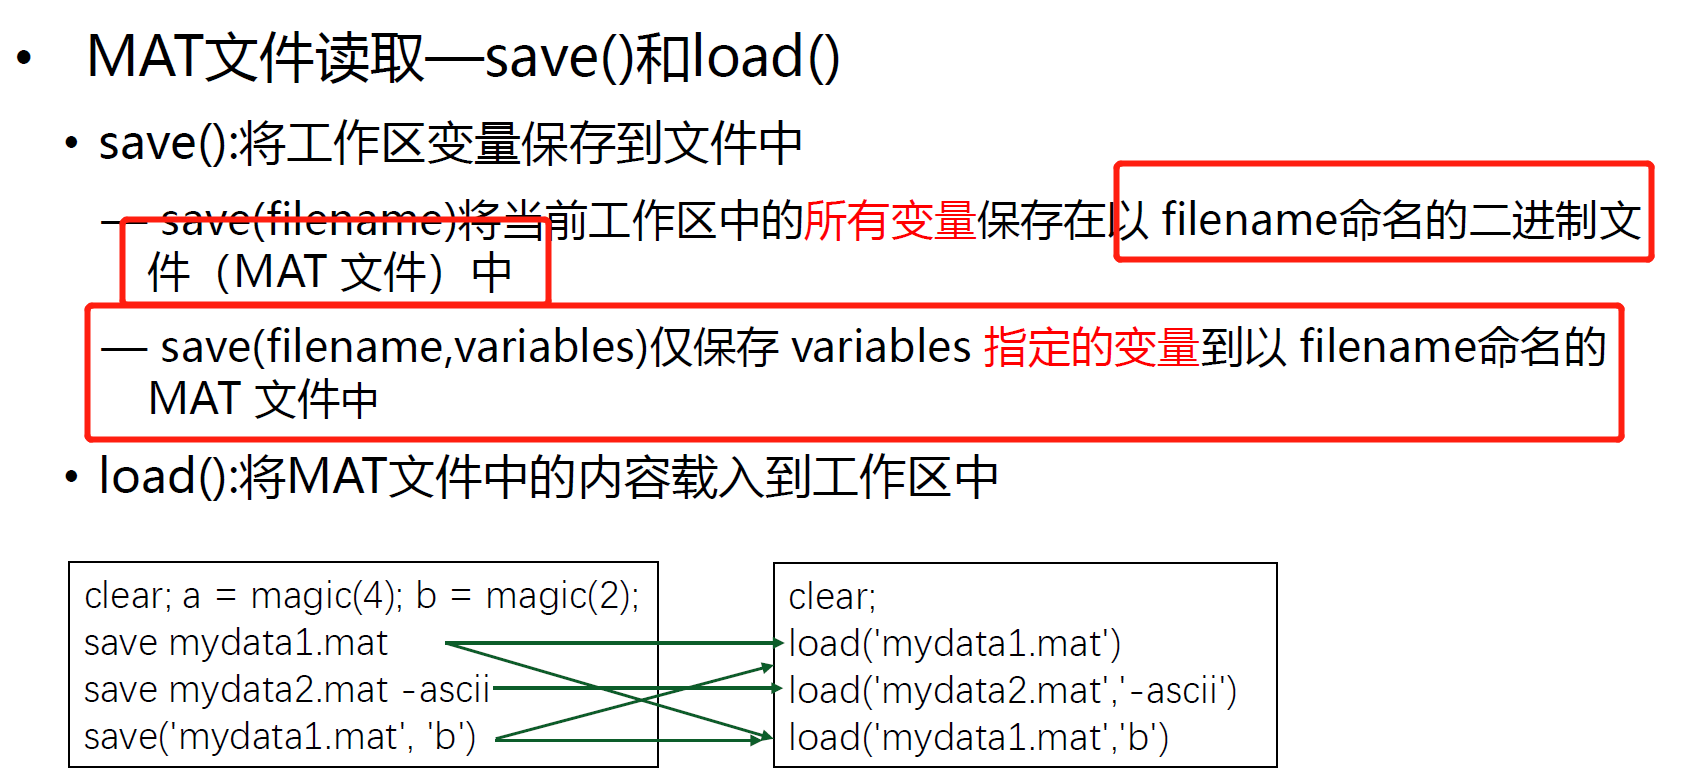

### Excel文件读取—xlsread()

clear all;
score1 = xlsread('data.xlsx');

错误使用 xlsread
无法打开文件 'data.xlsx'。
未找到文件 'C:\Users\data.xlsx'。

score2 = xlsread('data.xlsx','B2:D4');
[num,txt] = xlsread('data.xlsx');

### Excel文件写入—xlswirte()

### 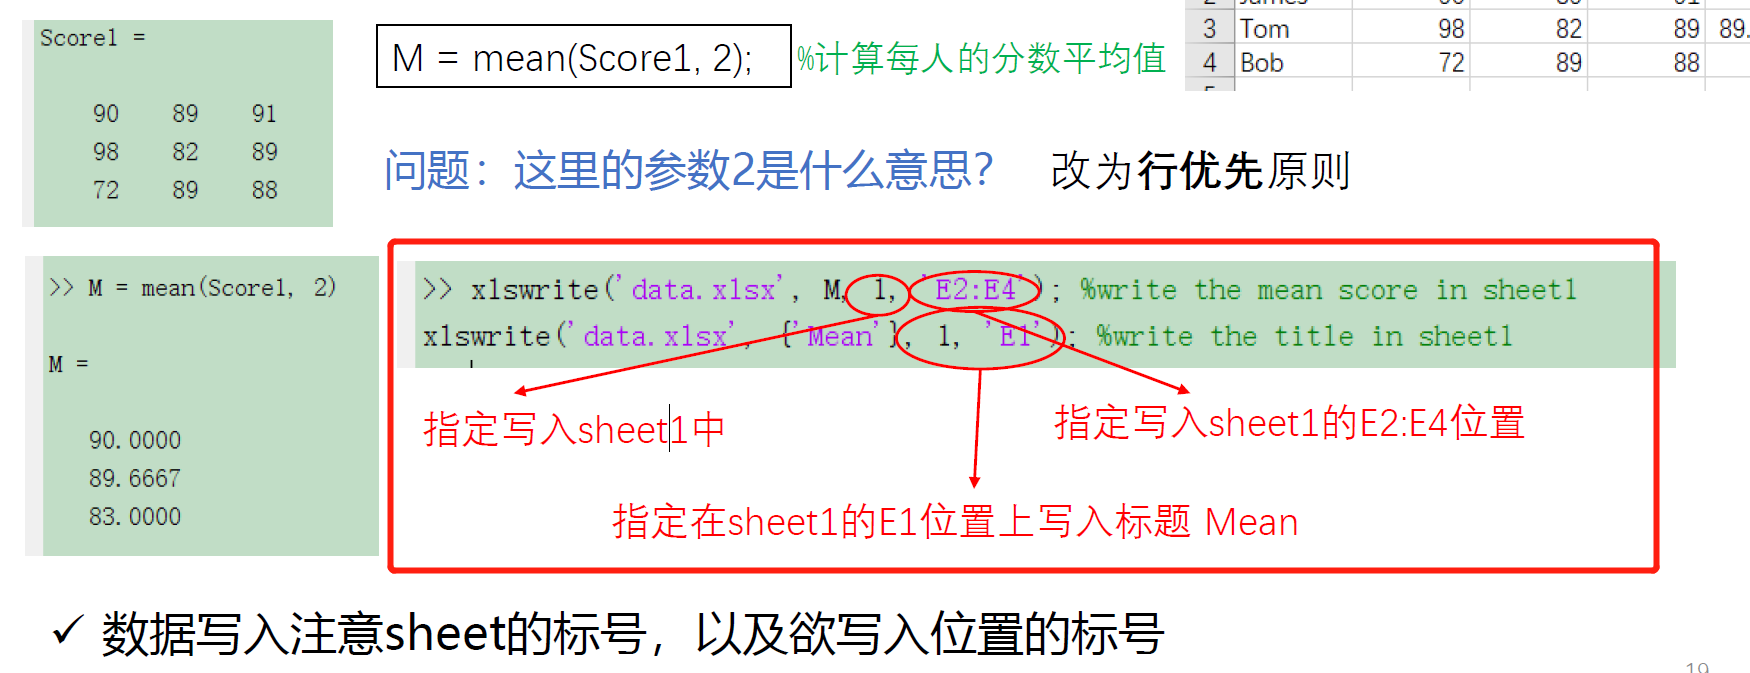

### TXT文件读取—fscanf()和fprintf()

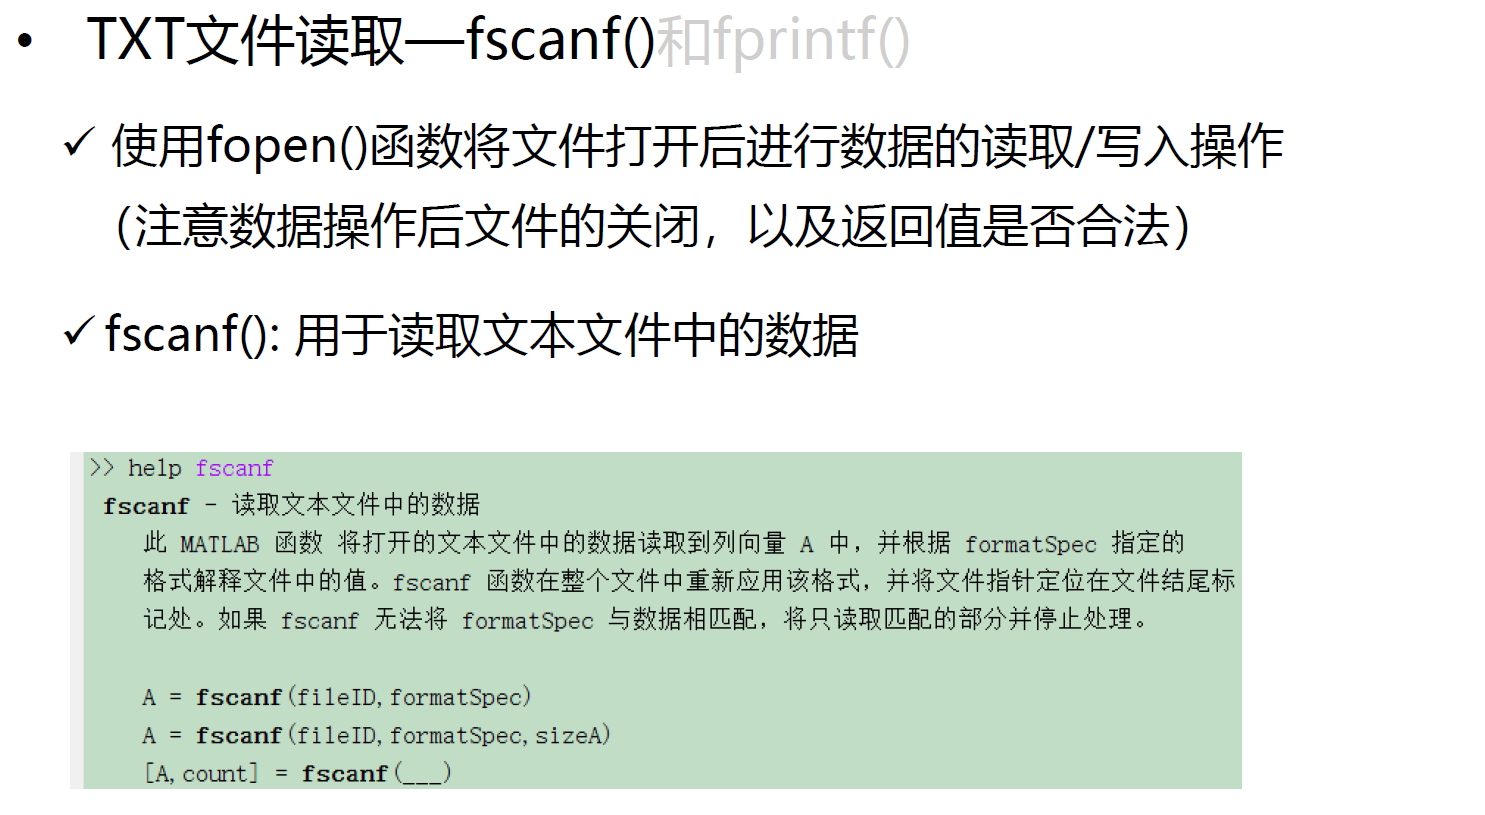

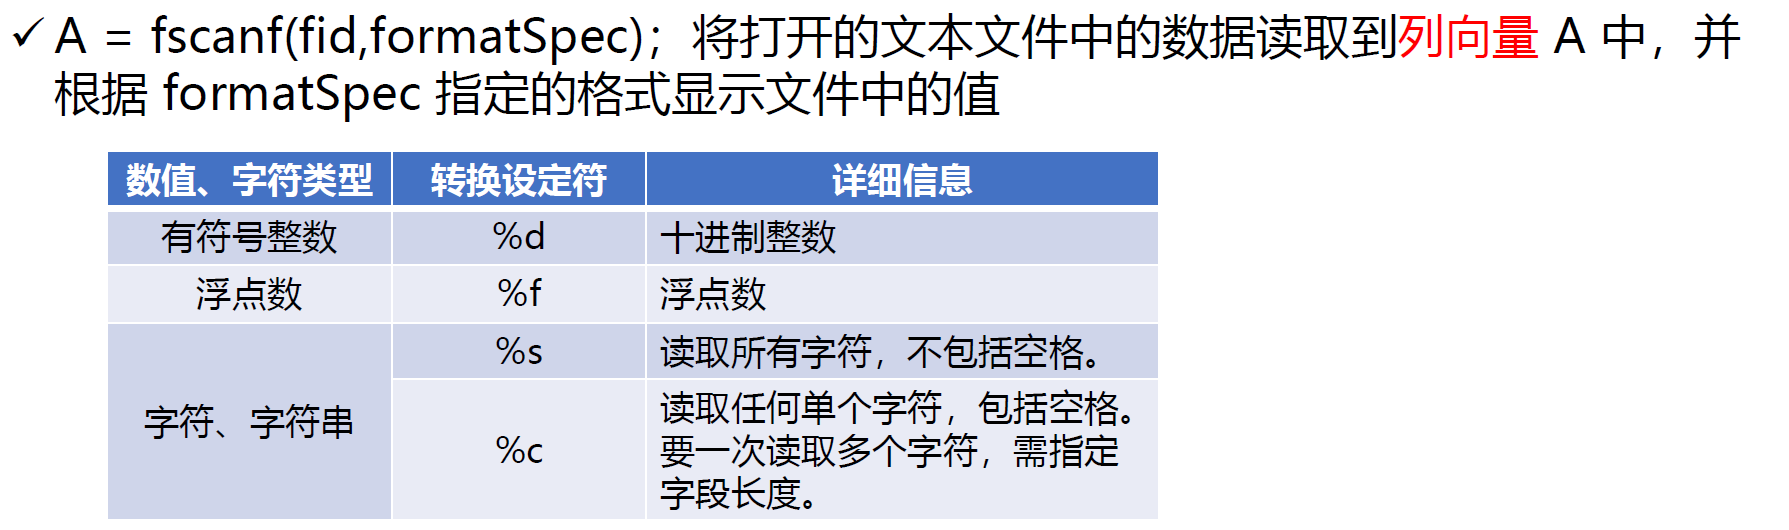

## 其它函数简介